# The ISETCam scene 

**Description**

ISETCam is structured around a few key objects that are important parts of the image acquisition pipeline. These are the **scene, optical image, sensor, and image processor**. This script introduces the WsISETCam **scene**.

A main goal of this script is to illustrate the ISETCam programming style. By using ISETCam objects properly, the code and analysis are much easier to understand. 

The implementation of these objects was written before Matlab implemented its classes and thus doesn't rely on that feature. But many of the principles are the same. For each object there are three fundamental operations: **Create, set parameters, and get** object parameters.

The scene describes the spectral radiance field. For the present tutorial we work with a simple planar radiance image, such as the image on a display surface.

We have substantially extended ISETCam for implementations for 3D scenes in the github repository (iset3d).

**Note**

- Use t_<TAB> to see the list of ISET tutorials

- Use s_<TAB> to see the list of ISET scripts.

**Reference Notes**

**Discussion**

- [Matlab classes](http://www.mathworks.com/help/matlab/matlab_oop/getting-familiar-with-classes.html)

- [scenes in perception](http://en.wikipedia.org/wiki/Scene_(perception))

**See also** sceneFromFile, sceneGet, sceneSet, scenePlot, sceneCreate, t_IntroductionOI.m

## At the beginning of a session, we usually initialize ISETCam

ieInit

## Create a scene and explore some of its features

The create function initiates the object. Typically, there are many different initial formats. For the scene, the optics including color targets, patterns, charts, and images.

The ISETCam function sceneCreate builds a number of predefined scenes that are useful for testing image systems. You can see the range of possibilities by typing

- help sceneCreate , or

- doc sceneScreate

into the Matlab prompt.

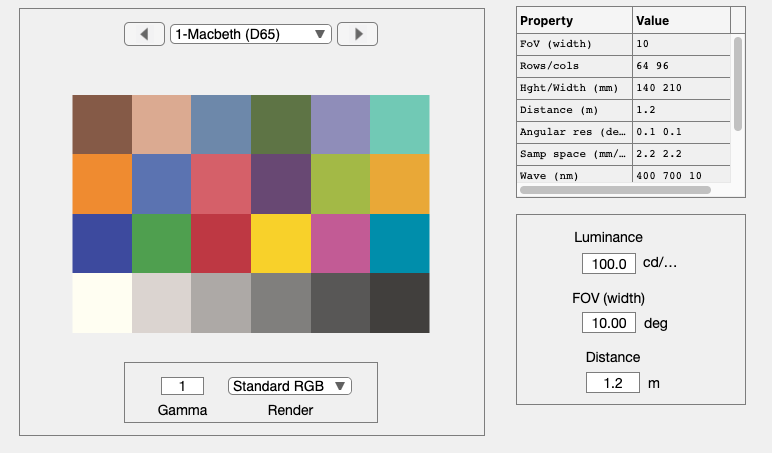

% Create a scene: Here is a simple scene of a color chart
scene = sceneCreate('macbeth d65');

% Then we call the function sceneWindow which displays the object This call
% opens the  graphical interface and displays the current scene
sceneWindow(scene);

When the window appears, you can scale the window size and adjust the font size as well (Edit | Change Font Size). There are many other options in the pull down menus for cropping, transposing, and measuring scene properties.

The command

is equivalent to

## The way to interact with an object is through gets and sets.

For example, each object has a name and a type.

name  = sceneGet(scene,'name')

name = 'Macbeth (D65)'

## There are many other scene parameters you can get

For example a scene has a horizontal field of view

hFOV = sceneGet(scene,'hfov')

hFOV = 10

## Use sceneSet to change a scene property

scene = sceneSet(scene,'hfov',0.5);  % In degrees of visual angle

% Confirm that the set worked
hFOV  = sceneGet(scene,'hfov')

hFOV = 0.5000

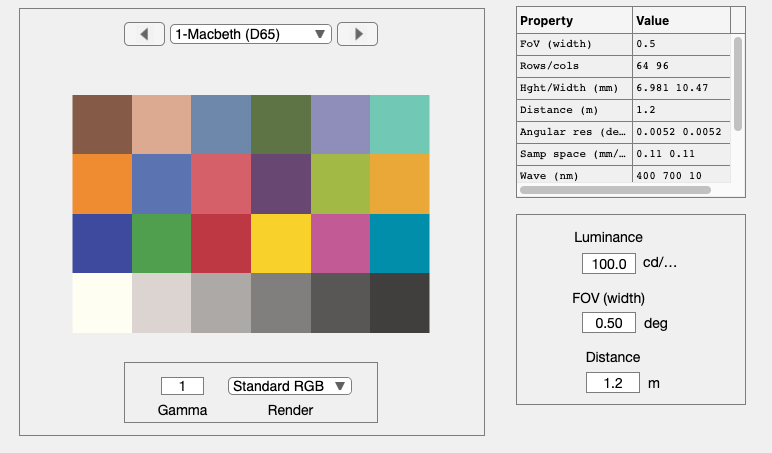


% Show the changes in the window.
ieReplaceObject(scene);

% And now refresh the window
sceneWindow;

## Philosophical interlude - programming issues

There are always more parameters to "get" than are to "set".  This is because there are dependencies among any object parameters.  For example, if you know the image distance and horizontal field of view, you can compute the spatial sample spacing.

In designing the sets/gets, the author must select an approach:  Do we allow the user to set anything and then update the other parameters for consistency, or do we only allow the user to set specific parameters and through this limitation enforce consistency.  ISETCam uses the 2nd method: Only some parameters can be set.

That is why there are more gets than sets.  You can get parameters that depend on the sets. You can see the scene structure and its parameters simply by typing the scene parameter

## Use sets and gets to interact with ISETCam objects

While the objects in ISETCam can be addressed directly - please don't. If you are ever tempted to set the objects directly, go get a cup of coffee. When you come back, you will feel like using a sceneSet

You can see the scene parameters you can set by typing 

For a nicer formatting, use the Matlab doc command. For example, you might try

## Explore the relationship between parameters

To see an example of the dependence, consider the effect of scene distance, which we can get, on scene sample spacing.

dist    = sceneGet(scene,'distance','mm')
spacing = sceneGet(scene,'sample spacing','mm')

If we move the scene closer, and we maintain the same number of row and column samples, the spacing changes.

scene = sceneSet(scene,'distance',0.6);

dist = 1200

sceneGet(scene,'sample spacing','mm')

spacing =     0.1091    0.1091


## Change the distance and horizontal field of view (hFOV)

This will change the sample spacing as well.

scene = sceneSet(scene,'hfov',hFOV/2);
sceneGet(scene,'sample spacing','mm')

ans =     0.0545    0.0545


## Specifying units

In this example, we specified the units of the sample spacing as millimemters (mm). We could have specified microns.

sceneGet(scene,'sample spacing','um')

or we could have specified the return in meters.

sceneGet(scene,'sample spacing','m')

ans =     0.0273    0.0273


## Creating a scene from a file

ISETCam includes a few multispectral scenes.  These are large files, so the default distribution only includes one example.  We have another 100 or so that are available.

fname = fullfile(isetRootPath,'data','images','multispectral','StuffedAnimals_tungsten-hdrs.mat');

ans =    27.2708   27.2708


scene = sceneFromFile(fname,'multispectral');
sceneWindow(scene);

## Plot scene properties

Many scene properties that can be plotted either from the scene Window or using scenePlot. For example, ISETCam scenes specify a uniform illuminant by default.  You can plot the illuminant in energy units by this command.

scenePlot(scene,'illuminant energy');

ans = 1.0e-04 *

    0.2727    0.2727


The scenePlot command above is equivalent to

## You can change the illumination's spectral power distribution

In this case, we create a blackbody illuminant and reilluminate the scene.

bb = blackbody(sceneGet(scene,'wave'),5500,'energy');
scene = sceneAdjustIlluminant(scene,bb);

Reading multispectral data with mcCOEF.
Saved using svd method


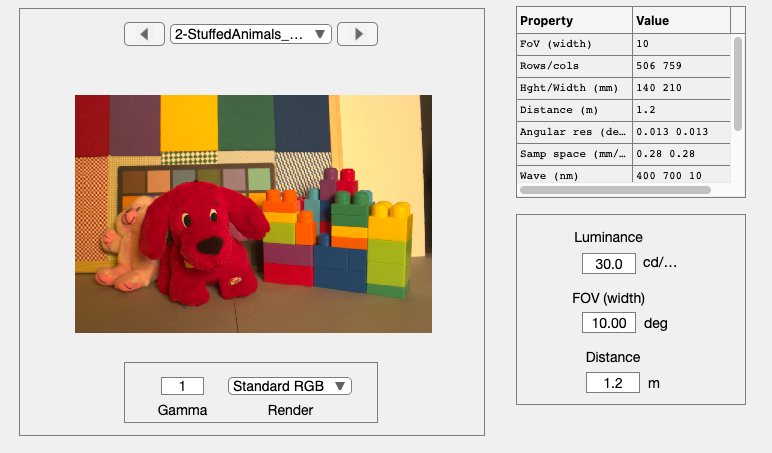

sceneWindow(scene);

## ISETCam keeps track of units

In this case, we plot the illuminant in units of photons, rather than energy.

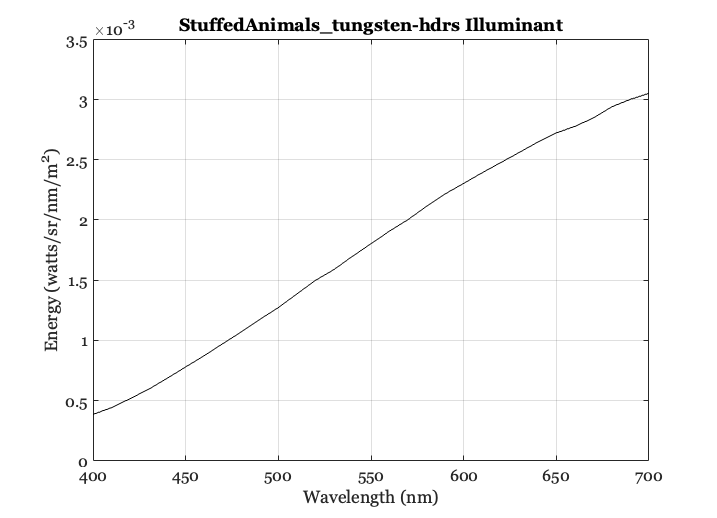

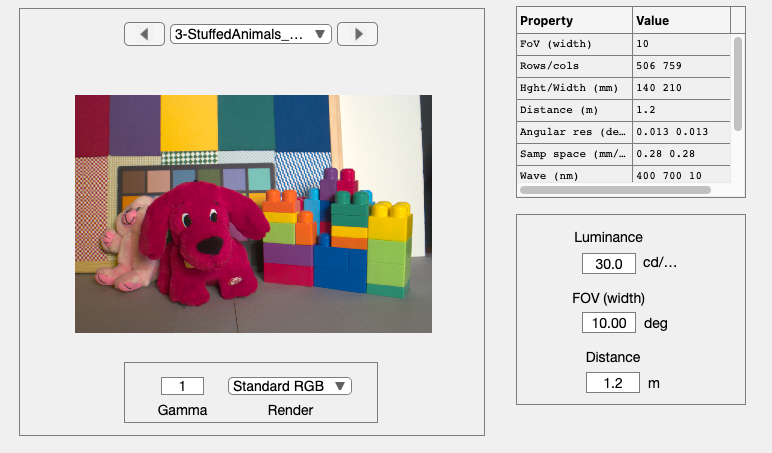

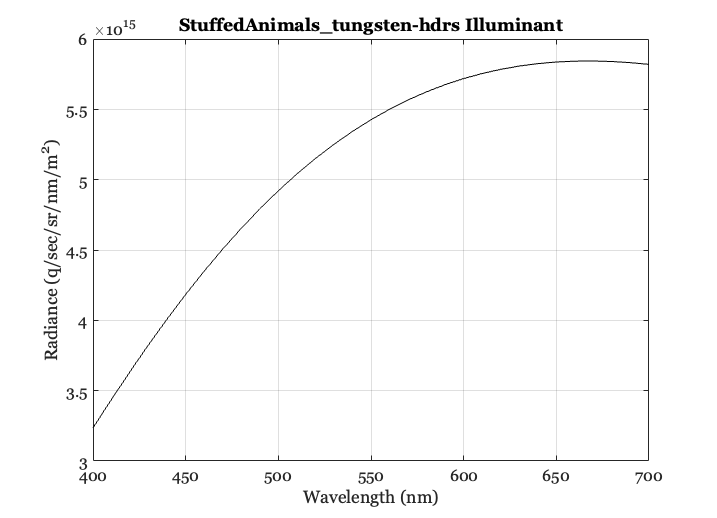

scenePlot(scene,'illuminant photons');